# RBE 501 - Homework 2

*Author: Keith Chester*

*E-mail: kchester@wpi.edu*

This file covers homework 2, problem 1, at multiple stages.

The purpose of the homework was to utilize product exponentials to do forward kinematics, determine and analyze the Jacobian of the given arm for singularities, utilize it for velocity analysis, and also perform inverse kinematics utilizing the Jaocbian.

### 1.B)

Below, we construct the robotic arm by defining our observable $\omega$ and *q* values.

We hten solve for the $e^{\left\lbrack S\right\rbrack \theta }$ for each joint.

syms theta

arm = [
        struct("omega", [0; 0; 1;], "q", [0; 0; 0;], "joint", "revolute");
        struct("omega", [0; -1; 0;], "q", [150; 0; 475;], "joint", "revolute");
        struct("omega", [0; -1; 0;], "q", [150; 0; 1075;], "joint", "revolute");
        struct("omega", [0; 0; 1;], "q", [870; 0; 1195;], "joint", "revolute");
      ]

arm = 4×1 struct array with fields:
    omega
    q
    joint



% e_st for 0
display("0")

    "0"



omega = [0;0;1];
q = [0;0;0;];
get_e_wt(omega, theta);
e_st_0 = get_e_st(omega, q, theta, "revolute")

$$e\_st\_0 = \left(\begin{array}{cccc} \cos\left(\theta \right) & -\sin\left(\theta \right) & 0 & 0\\ \sin\left(\theta \right) & \cos\left(\theta \right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


% e_st for 1
display("1")

    "1"



omega = [0;-1;0];
q = [150;0;475;];
get_e_wt(omega, theta);
e_st_1 = get_e_st(omega, q, theta, "revolute")

$$e\_st\_1 = \left(\begin{array}{cccc} \cos\left(\theta \right) & 0 & -\sin\left(\theta \right) & 475\,\sin\left(\theta \right)-150\,\cos\left(\theta \right)+150\\ 0 & 1 & 0 & 0\\ \sin\left(\theta \right) & 0 & \cos\left(\theta \right) & 475-150\,\sin\left(\theta \right)-475\,\cos\left(\theta \right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$


% e_st for 2
display("2")

    "2"



omega = [0;-1;0];
q = [150;0;1075;];
get_e_wt(omega, theta);
e_st_2 = get_e_st(omega, q, theta, "revolute")

$$e\_st\_2 = \left(\begin{array}{cccc} \cos\left(\theta \right) & 0 & -\sin\left(\theta \right) & 1075\,\sin\left(\theta \right)-150\,\cos\left(\theta \right)+150\\ 0 & 1 & 0 & 0\\ \sin\left(\theta \right) & 0 & \cos\left(\theta \right) & 1075-150\,\sin\left(\theta \right)-1075\,\cos\left(\theta \right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$


display("ee")

    "ee"



omega = [0;0;1;];
q = [870;0;1195;];
e_st_ee = get_e_st(omega, q, theta, "revolute")

$$e\_st\_ee = \left(\begin{array}{cccc} \cos\left(\theta \right) & -\sin\left(\theta \right) & 0 & 870-870\,\cos\left(\theta \right)\\ \sin\left(\theta \right) & \cos\left(\theta \right) & 0 & -870\,\sin\left(\theta \right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

The product of exponentials approach to forward kinematics does not provide us an easy way to determine the position of frames of joints that are not the end effector easily. To accomplish this, we will define a separate *M* matrix for each joint, such that we can later use a sub-selection of the generated $e^{\left\lbrack S\right\rbrack \theta }$'s in order to determine the transformation matrix for each joint.


M_0ee = [1 0 0 870; 0 1 0 0; 0 0 1 1195; 0 0 0 1;];
M_01 = [1 0 0 150; 0 0 -1 0; 0 1 0 475; 0 0 0 1;];
M_02 = [1 0 0 150; 0 0 -1 0; 0 1 0 1075; 0 0 0 1;];
Ms = {eye(4); M_01; M_02; M_0ee};
thetas = [0, 0, 0];
ests = {e_st_0; e_st_1; e_st_2;, eye(4)}

ests = 4×1 cell array
    {4×4 sym   }
    {4×4 sym   }
    {4×4 sym   }
    {4×4 double}


Here we create a function, **get_jacobian**, which accepts each of the generated *M* matricies, the $e^{\left\lbrack S\right\rbrack \theta }$'s, and symbolic or numeric theta values, to generate the Jacobian for our given arm.

J_0 = get_jacobian(Ms, ests, thetas)

$$J\_0 = \left(\begin{array}{ccc} 0 & -720 & -120\\ 870 & 0 & 0\\ 0 & 720 & 720\\ 0 & 0 & 0\\ 0 & -1 & -1\\ 1 & 0 & 0 \end{array}\right)$$


syms theta0 theta1 theta2
thetas = [theta0, theta1, theta2]

$$thetas = \left(\begin{array}{ccc} \theta_{0} & \theta_{1} & \theta_{2} \end{array}\right)$$

J = simplify(get_jacobian(Ms, ests, thetas))

$$J = \begin{array}{l} \left(\begin{array}{ccc} -30\,\sin\left(\theta_{0}\right)\,\sigma_{1} & -120\,\cos\left(\theta_{0}\right)\,\sigma_{2} & -\cos\left(\theta_{0}\right)\,\sigma_{3}\\ 30\,\cos\left(\theta_{0}\right)\,\sigma_{1} & -120\,\sin\left(\theta_{0}\right)\,\sigma_{2} & -\sin\left(\theta_{0}\right)\,\sigma_{3}\\ 0 & \sigma_{4}-600\,\sin\left(\theta_{1}\right) & \sigma_{4}\\ 0 & \sin\left(\theta_{0}\right) & \sin\left(\theta_{0}\right)\\ 0 & -\cos\left(\theta_{0}\right) & -\cos\left(\theta_{0}\right)\\ 1 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=24\,\cos\left(\theta_{1}+\theta_{2}\right)-4\,\sin\left(\theta_{1}+\theta_{2}\right)-20\,\sin\left(\theta_{1}\right)+5\\ \sigma_{2}=\cos\left(\theta_{1}+\theta_{2}\right)+6\,\sin\left(\theta_{1}+\theta_{2}\right)+5\,\cos\left(\theta_{1}\right)\\ \sigma_{3}=120\,\cos\left(\theta_{1}+\theta_{2}\right)+720\,\sin\left(\theta_{1}+\theta_{2}\right)\\ \sigma_{4}=120\,\sqrt{37}\,\cos\left(\theta_{1}+\theta_{2}+\mathrm{atan}\left(\frac{1}{6}\right)\right) \end{array}$$

Using symbolics, we see that we have a complicated Jacobian. We will utilize this value for later conversions.

Now that we have the Jacobian determined, we can utilize it to solve for the inverse kinematics. We utilize the **inverse_kinematics** function, defined below, to numerically attempt to solve with minimal error the joint positions required to have the end effect reach the desired ${\left\lbrack \begin{array}{ccc}
500 & 100 & 1500
\end{array}\right\rbrack }^T$ *xyz* position.

[thetas, xyz, err, i] = inverse_kinematics(arm, M_0ee, J, [500; 100; 1500], .1)

thetas =     0.1974
    0.3500
    0.1691


xyz = 	1.0e+03 *

    0.4999
    0.1000
    1.4999


err =     0.0627
    0.0094
    0.0637


i = 4

Once we have the resulting joint thetas for the given position, we can utilize the symbolic Jacobian we created above and fill in the calculated thetas. This gives us the numeric Jacobian for this given position.

J_B = double(subs(J, [theta0, theta1, theta2], transpose(thetas)))

J_B = 	1.0e+03 *

   -0.1000   -1.0051   -0.4524
    0.5000   -0.2010   -0.0905
         0    0.3599    0.5656
         0    0.0002    0.0002
         0   -0.0010   -0.0010
    0.0010         0         0


Finally, we can solve for $\dot{q}$ by solving $\dot{q} =J^{-1} \dot{p}$.

q_dot = pinv(J_B) * [5; 5; 10; 0; 0; 0;] % padding for matrix size matchup

q_dot =     0.0077
   -0.0192
    0.0299


### 1.C)

Here, we attempt to utilize the Jacobian determined above to discover singularities. We take the $J_v$ upper section of the 6x3 matrix for simplicity and simplify it for easier calculation. We then have MATLAB solve for our theta values.

J_v = simplify(J(1:3,1:3))

$$J\_v = \begin{array}{l} \left(\begin{array}{ccc} -30\,\sin\left(\theta_{0}\right)\,\sigma_{1} & -120\,\cos\left(\theta_{0}\right)\,\sigma_{2} & -\cos\left(\theta_{0}\right)\,\sigma_{3}\\ 30\,\cos\left(\theta_{0}\right)\,\sigma_{1} & -120\,\sin\left(\theta_{0}\right)\,\sigma_{2} & -\sin\left(\theta_{0}\right)\,\sigma_{3}\\ 0 & \sigma_{4}-600\,\sin\left(\theta_{1}\right) & \sigma_{4} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=24\,\cos\left(\theta_{1}+\theta_{2}\right)-4\,\sin\left(\theta_{1}+\theta_{2}\right)-20\,\sin\left(\theta_{1}\right)+5\\ \sigma_{2}=\cos\left(\theta_{1}+\theta_{2}\right)+6\,\sin\left(\theta_{1}+\theta_{2}\right)+5\,\cos\left(\theta_{1}\right)\\ \sigma_{3}=120\,\cos\left(\theta_{1}+\theta_{2}\right)+720\,\sin\left(\theta_{1}+\theta_{2}\right)\\ \sigma_{4}=120\,\sqrt{37}\,\cos\left(\theta_{1}+\theta_{2}+\mathrm{atan}\left(\frac{1}{6}\right)\right) \end{array}$$

det_J_v = simplify(det(J_v))

$$det\_J\_v = 8640000\,\cos\left(\theta_{1}\right)+64800000\,\cos\left(\theta_{2}\right)+51840000\,\sin\left(\theta_{1}\right)-10800000\,\sin\left(\theta_{2}\right)-259200000\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)+43200000\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)+302400000\,\cos\left(\theta_{1}\right)\,{\cos\left(\theta_{2}\right)}^{2}-103680000\,{\cos\left(\theta_{2}\right)}^{2}\,\sin\left(\theta_{1}\right)-302400000\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)-103680000\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{2}\right)$$

results = solve(det_J_v==0, [theta0, theta1,theta2]);

Here we look at each result:

results.theta0

$$ans = 0$$

results.theta1

$$ans = 0.7695705080326730348789198818723$$

results.theta2

$$ans = 0.26086770513215262064837416870167$$

To confirm our position with the given thetas, we now perform forward kinematics with them to look at the resulting end effector position:

T_0ee = double(fk_screw(arm, M_0ee, [results.theta0; results.theta1; results.theta2; 0;], "base"));
p_ee = T_0ee(1:3,4)

p_ee = 	1.0e+03 *

    0.0000
         0
    1.5851


As expected, $x==y==0$, denoting this as an "overhead" singularity, where the end effector is effectively over the rotational axis of joint 0. It does not matter the value of $\theta_0$in this instance - any value is a singular configuration.

### 1.D)

In this section, we develop an interactive inverse kinematic solver for the arm with a plotted "simulation" of the arm.

Please note that for this to run correctly, all of the code above must be executed first.

If a position outside the work envelope is specified, the inverse kinematics solver will max its iterations and note that the position could not be solved.

Positions are solved within a .1 mm error.

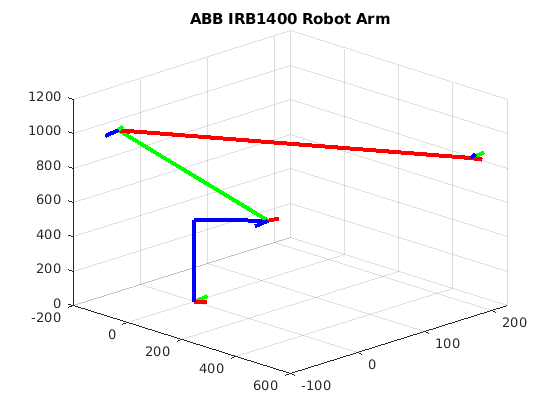

x = 525;
y = 200;
z = 850;

 

% First we try and determine the IK of the robot. If we fail, we stop here
[thetas, xyz, err, i] = inverse_kinematics(arm, M_0ee, J, [x; y; z;], .1);
if norm(err) > 1
    display("The error of the IK was too high, we could not converge on this location. It is likely not reachable by the arm");
    return
end

% The following code will draw the robot arm in the given setup if it can
% be done
figure
title("ABB IRB1400 Robot Arm")
grid on
hold on
% axis([-1000 1000 -1000 1000 0 1000])
view([45 25])

% Figure out the location of each limb based on the new thetas and forward
% kinematics
T = {};

thetas_draw = [thetas; 0;];
for i = 1:length(thetas_draw)
    M = Ms{i};
    theta_i = thetas_draw(i);
    
    T_0_i = 1;
    for j = 1:i
        e_st = subs(ests{j}, theta, thetas_draw(j));
        T_0_i = T_0_i * e_st;
    end
    T_0_i = T_0_i * M;
    T_0_i = double(T_0_i);
    T{end+1} = T_0_i;

end

% T is now a cell array with the T_0i for each frame from origin. So
% Let's draw them. Frames first, then lines between the amrs.
draw_axes_for_transforms(T, 25);
origin = [0;0;0;1;];
elbow = [0; 0; 475;];
j1 = T{1} * origin;
j2 = T{2} * origin;
j3 = T{3} * origin;
ee = T{4} * origin;

line('XData', [j1(1) elbow(1)], 'YData', [j1(2) elbow(2)], 'ZData', [j1(3) elbow(3)], 'Color', 'blue', 'LineWidth', 3);
line('XData', [elbow(1) j2(1)], 'YData', [elbow(2) j2(2)], 'ZData', [elbow(3) j2(3)], 'Color', 'blue', 'LineWidth', 3);
line('XData', [j2(1) j3(1)], 'YData', [j2(2) j3(2)], 'ZData', [j2(3) j3(3)], 'Color', 'green', 'LineWidth', 3);
line('XData', [j3(1) ee(1)], 'YData', [j3(2) ee(2)], 'ZData', [j3(3) ee(3)], 'Color', 'red', 'LineWidth', 3);

hold off

## Functions

This section contains many of the helper functions we created to power these answers.

### Get [w] 

Given an omega value, return the skew representation of omega.

function omega_skew = get_skew(omega)
    omega_skew = [0 -omega(3), omega(2); omega(3) 0 -omega(1); -omega(2) omega(1) 0;];
end

### Get v

For a given revolute joint, return the value of *v*.

function v = get_v(omega, q)
    v = cross(-omega,q);
end

### Get e_wt $e^{\left\lbrack \omega \right\rbrack \theta }$

Given an omega and theta value (possibly symbolic), return $e^{\left\lbrack \omega \right\rbrack \theta }$.

function e_wt = get_e_wt(omega, theta)
    omega_skew = get_skew(omega);
    e_wt = eye(3) + sin(theta)*omega_skew+(1-cos(theta))*omega_skew^2;
end

### Get e_st $e^{\left\lbrack S\right\rbrack \theta }$

Given a robot joint (either prismatic or revolute), calculate $e^{\left\lbrack S\right\rbrack \theta }$.

function e_st = get_e_st(omega, q, theta, joint_type)
    I = eye(3);
    
    if joint_type == "revolute"
        omega_skew = get_skew(omega);
        e_wt = get_e_wt(omega, theta);
        v = get_v(omega, q);
        vt = (I*theta+(1-cos(theta))*omega_skew+(theta-sin(theta))*omega_skew^2)*v;
        e_st = [e_wt vt; 0 0 0 1];
    else
        % In MATLAB, you can't have an array of structs with non
        % matching fields. Bah. To cheat, in prismatic joints omega
        % == v even though mathematically this isn't true.
        v = omega;
        vt = v*theta;
        e_st = [I vt; 0 0 0 1];  
    end    
end

### Forward Kinematics Screw Function

Given the arm configuration (omega and q values), and the initial M transformation matrix between base and end effector positions at home position, calculate the forward kinematics of the system for a given set of thetas. The "frame" can be changed to "base" or "ee" depending on which frame of reference you are using.

function T = fk_screw(arm, M, thetas, frame)
    if frame == "base"
        T = 1;
    else
        T = M;
    end
    
    I = eye(3);
    
    for index = 1:length(arm)
        q = arm(index).q;
        omega = arm(index).omega;
        joint_type = arm(index).joint;
        theta = thetas(index);
        
        e_st = get_e_st(omega, q, theta, joint_type);
        T = T * e_st;
    end
    
    if frame == "base"
        T = T * M;
    end
end

### Get Jacobian

This function calculates the Jacobian given:

- A given M for the robotic arm

- a list of intermeidate joint $M$'s 

- a list of intermediate $e^{\left\lbrack S\right\rbrack \theta }$'s per joint

- a list of expected thetas for each joint

It assumes that the variable *theta* ($\theta$) is utilized and replaces it within the given $e^{\left\lbrack S\right\rbrack \theta }$, preventing the need to recalculate $e^{\left\lbrack S\right\rbrack \theta }$ repeatedly. We assume that the M's and $e^{\left\lbrack S\right\rbrack \theta }$'s are arranged in a matching ascending order, from base to the last joint.

function J = get_jacobian(Ms, ests, thetas)
    syms theta
    J = sym(zeros(6, length(thetas)));
    
    % First we discover what the resulting T_0ee - or, transformation to
    % the end effector frame from the base frame- is.
    T_0_ee = 1;
    for i = 1:length(thetas)
        T_0_ee = T_0_ee * subs(ests{i}, theta, thetas(i));
    end
    
    T_0_ee = T_0_ee * Ms{length(Ms)};
    % Now grab the translation for the EE
    o_ee = T_0_ee(1:3,4);
    
    for i = 1:length(thetas)
        M = Ms{i};
        theta_i = thetas(i);
        
        T_0_i = 1;
        for j = 1:i
            e_st = subs(ests{j}, theta, thetas(j));
            T_0_i = T_0_i * e_st;
        end

        T_0_i = T_0_i * M;
    
        z = T_0_i(1:3, 3);
        o = o_ee - T_0_i(1:3, 4);
        
        J_p = cross(z, o);
        J_o = z;
        J_i = [J_p; J_o];

        J(1:6,i) = J_i;
    end
    
end

### Inverse Kinematics Position

This function accepts necessary information about the arm such as the *M* transformation matrix of base to end effector at home position, the arm's q and omega designations per joint, as well as the desired *xyz* position that the end effector of the arm should reach. We also take a maximum error allowed.

The function will then iterate - until a maximum of 25 iterations or an error lower than the requested maximum is reported - the joint values for the given arm. It utilizes the inverse Jacobian to attempt to determine the delta required in each iteration.

function [q_i, p_i, error, iterations] = inverse_kinematics(arm, M, J, xyz, error_max)
    syms theta0 theta1 theta2
    iterations = 0;
    
    q_i = zeros(length(arm)-1, 1);
    % For simplicty, just have the error be greater than allowed to 
    % force the first iteration
    error = ones(length(arm)-1, 1)*(error_max+1);
    p_i = xyz;
    all(abs(error) <= error_max);
    
    % As long sa our error is too high, iterate
    while ~all(abs(error) <= error_max)
        if iterations+1 > 100
            return
        end
        iterations = iterations + 1;
        
        % Find the current arm's position to set our position vectors 
        T = fk_screw(arm, M, [q_i; 0], "base");
        p_i = T(1:3, 4);
        
        J_i = double(subs(J, [theta0; theta1; theta2], q_i));
        delta_q = pinv(J_i)*[xyz-p_i; zeros(3,1)];
        
        q_i = q_i + delta_q;
        
        error = xyz-p_i;
    end
end

#### draw_coordinate_axis

This function accepts a specified transform, length of the desired axis lines, and the color for each axis. It then draws on the current active figure the origin for that axis based on the transform passed.

function [x_line, y_line, z_line] = draw_coordinate_axis(transform, length, x_color, y_color, z_color)    
    origin = transform * [0; 0; 0; 1;];
    x = transform * [length; 0;         0;      1; ];
    y = transform * [0;      length;    0;      1; ];
    z = transform * [0;      0;         length; 1; ];
    x_line = line('XData', [origin(1) x(1)], 'YData', [origin(2) x(2)], 'ZData', [origin(3) x(3)], 'Color', x_color, 'LineWidth', 3);
    y_line = line('XData', [origin(1) y(1)], 'YData', [origin(2) y(2)], 'ZData', [origin(3) y(3)], 'Color', y_color, 'LineWidth', 3);
    z_line = line('XData', [origin(1) z(1)], 'YData', [origin(2) z(2)], 'ZData', [origin(3) z(3)], 'Color', z_color, 'LineWidth', 3);
end

### draw_axes_for_transforms

Given a cell of transforms, draw each of them to a given size in the current active plot. It does this by calling **draw_coordinate_axis** above.

function lines = draw_axes_for_transforms(transforms, line_size)
    lines = [];
    for index = 1:length(transforms)
        [x_line, y_line, z_line] = draw_coordinate_axis(transforms{index}, line_size, 'red', 'green', 'blue');
        lines(end+1) = x_line;
        lines(end+1) = y_line;
        lines(end+1) = z_line;
    end
end